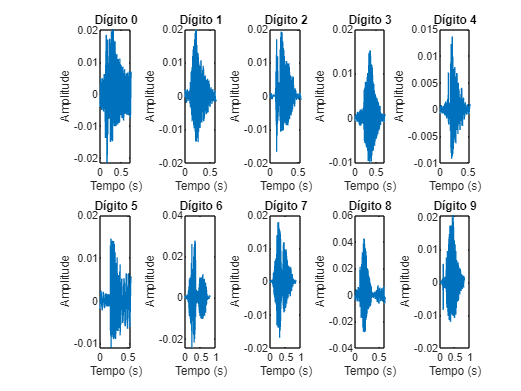

filePath = 'C:\Users\User\Desktop\uni\ATD\Projeto1\55\';
audioFiles = {'0_55_0.wav', '1_55_0.wav', '2_55_0.wav', '3_55_0.wav', '4_55_0.wav', '5_55_0.wav', '6_55_0.wav', '7_55_0.wav', '8_55_0.wav', '9_55_0.wav'};
y = cell(1, length(audioFiles));
%Importar os audio usando a função audioread
for i = 1:length(audioFiles)
    file = append(filePath, audioFiles{i});
    [y{i}, Fs] = audioread(file);
end

grafico(y, Fs);

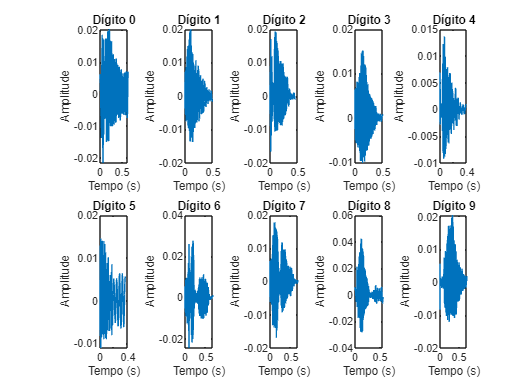


%Adicionar silencio no inicio
limite = 5e-3; %Limite que consideramos silenico ou seja sempre que o intervalo tem a amplitude maxima menor que 0.005
for j = 1:length(y)
    duracaoJanela = 0.002; %Tamanho da janela de pesquisa
    comprimentoJanela = duracaoJanela * Fs;
    comrimentoTotal = length(y{j});
    numeroJanelas = floor(comrimentoTotal / comprimentoJanela);
    yNovo = [];
    for i = 1 : numeroJanelas
        yJanela = y{j}((i-1)*comprimentoJanela+1:comprimentoJanela*i);
        if max(yJanela) > limite
            yNovo = y{j}((i-1)*comprimentoJanela+1:end);
            break;
        end
    end
    y{j} = yNovo;
end

figure;
grafico(y, Fs);


%Adicionar ou remover o silencio no fim
duracaoMax = 0.6 %Duração do audio com mais tempo antes do silencio

duracaoMax = 0.6000

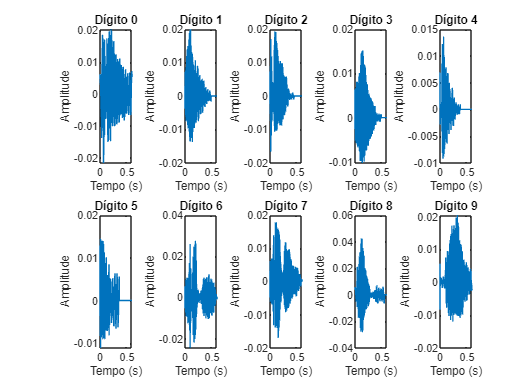

for i = 1:length(y)
    if(length(y{i}) < duracaoMax * Fs)
        y{i} = [y{i}; zeros(duracaoMax*Fs - length(y{i}), 1)];
    else
        y{i} = y{i}(1:duracaoMax*Fs);
    end
end

figure;
grafico(y, Fs);

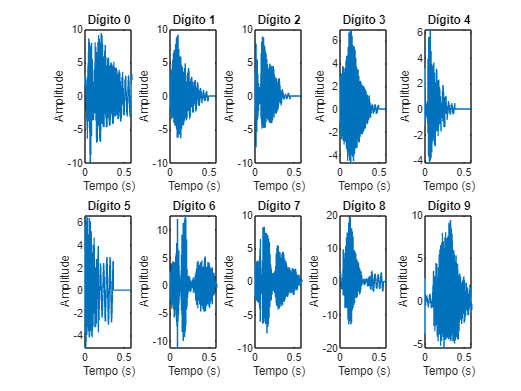


%Normalizar amplitude
amplitudeMax = max(abs(y{1}));
amplitudeMin = min(abs(y{1}));
for i = 2:length(y)
    amplitudeMaxAux = max(abs(y{i}));
    amplitudeMinAux = min(abs(y{i}));
    if amplitudeM > amplitudeMax
        amplitudeMax = amplitudeMaxAux;
    end
    if amplitudeMinAux < amplitudeMin
        amplitudeMin = amplitudeMinAux;
    end
end

valorMax = amplitudeMax / length(y);
valorMin = amplitudeMin / length(y);
for i = 1:length(y)
    y{i} = y{i} / valorMax;
end

figure;
grafico(y, Fs);

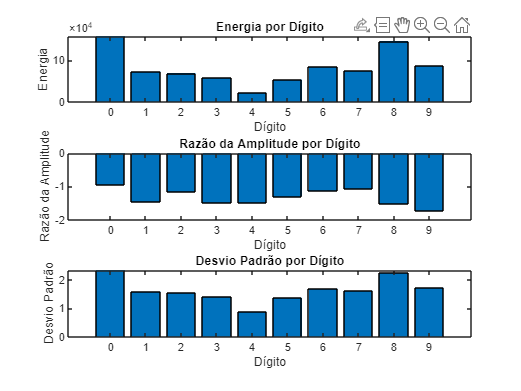


%Para este exercicio as 3 maneiras de destinguir o numero que escolhemos
%foram: energia de cada numero, amplitude máxima e desvio padrão
energia = zeros(1, length(y));
amplitudeMax = zeros(1, length(y));
amplitudeMin = zeros(1, length(y));
razaoAmplitude = zeros(1, length(y));
desvioPadrao = zeros(1, length(y));

for i = 1:length(y)
    energia(i) = sum(y{i}.^2);
    amplitudeMax(i) = max(y{i});
    amplitudeMin(i) = min(y{i});
    razaoAmplitude(i) = amplitudeMax(i) / amplitudeMin(i);
    desvioPadrao(i) = std(y{i});
end

figure;
subplot(3, 1, 1);
bar(0:9, energia);
xlabel('Dígito');
ylabel('Energia');
title('Energia por Dígito');

subplot(3, 1, 2);
bar(0:9, razaoAmplitude);
xlabel('Dígito');
ylabel('Razão da Amplitude');
title('Razão da Amplitude por Dígito');

subplot(3, 1, 3);
bar(0:9, desvioPadrao);
xlabel('Dígito');
ylabel('Desvio Padrão');
title('Desvio Padrão por Dígito');

function grafico(y, Fs)
for i = 1:length(y)
    subplot(2, 5, i)
    t = (0:length(y{i}) - 1) / Fs;
    plot(t, y{i});
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title(['Dígito ', num2str(i-1)]);
end
end